## **Environment Variables**

rho = 1.21; % Adjusted for 75m altitude
g = 9.81;

## Aerodynamic Coefficients and Wing Variables

AR = 6; % Assumption as it was not given
e = 0.85; % TBD after Wing Sizing %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
k = 1 / (pi * AR * e);
CD_min = 0.02; % Based on S1223
CL_TO = 1; % Based on S1223
CD_TO = 0.08; % Based on S1223
mu = 0.04;

## Target Parameters

V_cruise = 30; % > 25m/s limit
S_G = 8; % within 8 - 12m limit
theta_deg = 70; % > 60deg limit
V_climb = 3; % Assumption as it was not given

## Array Initialization

WS = linspace(10, 150, 200);

## Cruise Equation

q_cruise = 0.5 * rho * V_cruise^2;
TW_cruise = q_cruise * CD_min .* (1 ./ WS) + k * (1 / q_cruise) .* WS;

## Take-off Equation

CL_max = 2.22; % Based on S1223
V_stall = sqrt(2 .* WS / (rho * CL_max));
V_LOF = 1.1 * V_stall;
q_TO = 0.5 * rho * V_LOF.^2;
TW_takeoff = (V_LOF.^2) ./ (2 * g * S_G) + (q_TO .* CD_TO) ./ WS + mu .* (1 - (q_TO .* CL_TO) ./ WS);

## Turn Equation

n = 1 / cosd(theta_deg);
q_turn = 0.5 * rho * V_turn.^2;
TW_turn = q_turn .* (CD_min ./ WS + k .* (n ./ q_turn).^2 .* WS);

## Turn Equation

V_climb_fwd = 15;
q_climb = 0.5 * rho * V_climb_fwd^2;
TW_climb = (V_climb / V_climb_fwd) + (q_climb ./ WS) .* CD_min + (k / q_climb) .* WS;

## Plotting

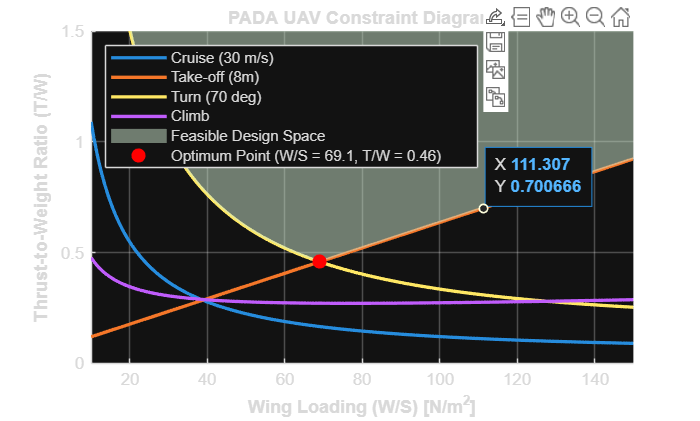

figure('Name', 'Propulsion Constraint Analysis', 'Color', 'w');
hold on; grid on;

plot(WS, TW_cruise, 'LineWidth', 2, 'DisplayName', 'Cruise (30 m/s)');
plot(WS, TW_takeoff, 'LineWidth', 2, 'DisplayName', 'Take-off (8m)');
plot(WS, TW_turn, 'LineWidth', 2, 'DisplayName', 'Turn (70 deg)');
plot(WS, TW_climb, 'LineWidth', 2, 'DisplayName', 'Climb');

TW_max_req = max([TW_cruise; TW_takeoff; TW_turn; TW_climb]);

[TW_opt, idx_opt] = min(TW_max_req);
WS_opt = WS(idx_opt);

fill([WS fliplr(WS)], [TW_max_req 2*ones(1, length(WS))], ...
    [0.8 0.9 0.8], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', 'Feasible Design Space');
plot(WS_opt, TW_opt, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r', ...
    'DisplayName', sprintf('Optimum Point (W/S = %.1f, T/W = %.2f)', WS_opt, TW_opt));

ylim([0 1.5]);
xlim([min(WS) max(WS)]);

xlabel('Wing Loading (W/S) [N/m^2]', 'FontWeight', 'bold');
ylabel('Thrust-to-Weight Ratio (T/W)', 'FontWeight', 'bold');
title('PADA UAV Constraint Diagram', 'FontWeight', 'bold');
legend('Location', 'northwest');
hold off;